% problem 1a
syms f(x,y)
f(x,y) = sqrt((2*x.^2)+(3*y.^3)-5);

$$f(x, y) = \sqrt{2\,x^{2}+3\,y^{3}-5}$$

fx = diff(f,x);
fy = diff(f,y);
fx_at_point = subs(fx, {x,y}, {3,2});
fy_at_point = subs(fy, {x,y}, {3,2});
fprintf('fx(3,2) = ');

fx(3,2) = 

disp(fx_at_point);

$$\frac{6\,\sqrt{37}}{37}$$

fprintf('fy(3,2) = ');

fy(3,2) = 

disp(fy_at_point);

$$\frac{18\,\sqrt{37}}{37}$$


% problem 1b
syms g(x,y,z)
g(x,y,z) = -x.*y.*exp(1)^(-x.^2*-y.^2)+z;
gxy = diff(diff(g,x),y);
gyx = diff(diff(g,y),x);
fprintf('gxy = ');

gxy = 

disp(gxy);

$$-{\left(\frac{6121026514868073}{2251799813685248}\right)}^{x^{2}\,y^{2}}-8\,{\left(\frac{6121026514868073}{2251799813685248}\right)}^{x^{2}\,y^{2}}\,x^{2}\,y^{2}\,\log\left(\frac{6121026514868073}{2251799813685248}\right)-4\,{\left(\frac{6121026514868073}{2251799813685248}\right)}^{x^{2}\,y^{2}}\,x^{4}\,y^{4}\,{\log\left(\frac{6121026514868073}{2251799813685248}\right)}^{2}$$

fprintf('gyx = ');

gyx = 

disp(gyx);

$$-{\left(\frac{6121026514868073}{2251799813685248}\right)}^{x^{2}\,y^{2}}-8\,{\left(\frac{6121026514868073}{2251799813685248}\right)}^{x^{2}\,y^{2}}\,x^{2}\,y^{2}\,\log\left(\frac{6121026514868073}{2251799813685248}\right)-4\,{\left(\frac{6121026514868073}{2251799813685248}\right)}^{x^{2}\,y^{2}}\,x^{4}\,y^{4}\,{\log\left(\frac{6121026514868073}{2251799813685248}\right)}^{2}$$

fprintf('gxy - gyx = ');

gxy - gyx = 

disp(gxy - gyx);

$$0$$


% problem 1c

The partial gzxy would be easiest because the partial with respect to z is 1, making the rest of the derivataion much easyer.

% problem 2a
syms h(x,y)
h(x,y) = y^2 - y^4 - x^2

$$h(x, y) = -x^{2}-y^{4}+y^{2}$$


hx = diff(h,x);
hy = diff(h,y);
[CPx, CPy] = solve(hx == 0, hy == 0, [x,y]);


The critial points of h(x,y) in the x direction are (0,0,0) and the critial point of h(x,y) in the y direction are (0, -sqrt(2)/2, sqrt(2)/2)

% Problem 2b
hxx = diff(h,x,2);
hyy = diff(h,y,2);
hxy = diff(diff(h,x),y);
D(x,y) = hxx*hyy - hxy^2;
[CPhx,CPhy] = solve(hx == 0, hy == 0)

$$CPhx = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$CPhy = \left(\begin{array}{c} 0\\ -\frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2} \end{array}\right)$$


for i = 1:length(CPx)
    D_val = subs(D, {x,y}, {CPx(i), CPy(i)});
    hxx_val = subs(hxx, {x,y}, {CPx(i), CPy(i)});
    
    fprintf('The point (%s, %s) ', char(CPx(i)), char(CPy(i)));

    if D_val > 0 && hxx_val < 0
        fprintf('the discriminant is greater than zero');
        fprintf('and the hxx value is less than zero ');
        fprintf('therefore the point is a local maximum.');
    elseif D_val > 0 && hxx_val > 0
        fprintf('the discriminant is greater than zero');
        fprintf('and the hxx value is greater than zero ');
        fprintf('therefore the point is a local minimum.');
    elseif D_val < 0
        fprintf('the discriminant is less than zero ')
        fprintf('therefore the point is a saddle point.');
    else
        fprintf('cannot be conclusivly determined as a local maximua or minimua');
    end
end

The point (0, 0) 

the discriminant is less than zero 

therefore the point is a saddle point.

The point (0, -2^(1/2)/2) 

the discriminant is greater than zero

and the hxx value is less than zero 

therefore the point is a local maximum.

The point (0, 2^(1/2)/2) 

the discriminant is greater than zero

and the hxx value is less than zero 

therefore the point is a local maximum.

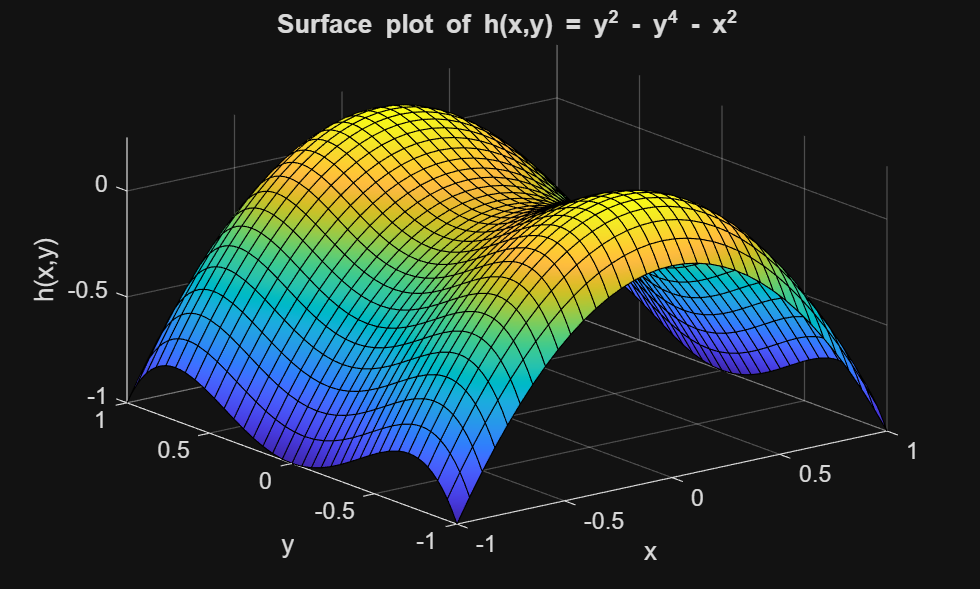

% Problem 2c
fsurf(h, [-1 1 -1 1]);
title('Surface plot of h(x,y) = y^2 - y^4 - x^2');
xlabel('x'); ylabel('y'); zlabel('h(x,y)');